# P21 Cx26 ABRs

defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\ABRs'

defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\ABRs'

cd(defaultDir);

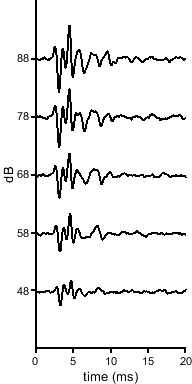

% load representative ABR click traces, plot 

addpath('cjk-2019_01_05-P21_cx26flfl_3');
flflCAP ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006};
figure
hold on
for x = 1:length(flflCAP)
    plot(flflCAP{1,x}.AverageData(:,1),flflCAP{1,x}.AverageData(:,4)-10*(x-1),'k','LineWidth',1.5)
end
dim = [2,4];
yticks([-40 -30 -20 -10 0]);
yticklabels([48 58 68 78 88])
xlim([0 20]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);

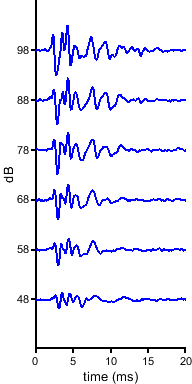


rmpath('cjk-2019_01_05-P21_cx26flfl_3');


addpath('cjk-2019_10_31-P21_abr_tectacx26fl+_7');
tectaCAP ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
figure
hold on
for x = 1:length(tectaCAP)
    plot(tectaCAP{1,x}.AverageData(:,1),tectaCAP{1,x}.AverageData(:,4)-10*(x-1),'b','LineWidth',1.5)
end
dim = [2,4];
yticks([-50 -40 -30 -20 -10 0]);
yticklabels([48 58 68 78 88 98])
xlim([0 20]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);

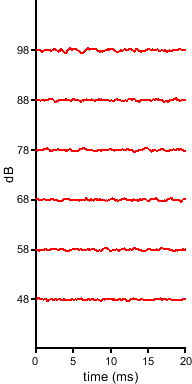


rmpath('cjk-2019_10_31-P21_abr_tectacx26fl+_7');

addpath('cjk-2019_10_07-P21_abr_tectacx26flfl_3');
tectaflCAP ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
figure
hold on
for x = 1:length(tectaflCAP)
    plot(tectaflCAP{1,x}.AverageData(:,1),tectaflCAP{1,x}.AverageData(:,4)-10*(x-1),'r', 'LineWidth',1.5)
end
dim = [2,4];
yticks([-50 -40 -30 -20 -10 0]);
yticklabels([48 58 68 78 88 98])
xlim([0 20]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);

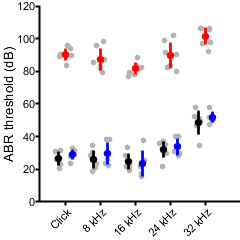

% Plot thresholds (currently in lab notebook), determine how to automate
tectaflclickp21 = [90.1,89.7,89.1,83.7,96.1,89.6,93.9];
tectafl8p21 = [85.2,87.4,83.1,79.1,95.8,82.0,98.1];
tectafl16p21 = [82.6,78.3,79.5,77.0,83.8,82.0,88.2];
tectafl24p21 = [82.4,79.9,83.4,90.5,98.9,91.7,101.9];
tectafl32p21 = [97.8,92.1,97.2,106,106,105.9,106];

tectaclickp21 = [23.8,28.1,28.9,31.8,32.8];
tecta8p21 = [26.3,23.7,22.6,38.1,38.1];
tecta16p21 = [17.7,15.6,21.9,37.8,25.3];
tecta24p21 = [29.9,28.3,39.9,40.0,30.8];
tecta32p21 = [51.7,52.0,57.7,50.1,47.4];

flflclickp21 = [27.1,22.8,20.3,31.8,31.1,26.2];
flfl8p21 = [18.7,23.7,20.9,30.2,34.7,28.4];
flfl16p21 = [21.6,23.6,21.6,33.4,28.6,19.1];
flfl24p21 = [21.8,29.9,36.1,34.9,37.1,33.0];
flfl32p21 = [34.5,50.9,57.8,49.5,52.6,46.7];

% plot all on one graph
figure
hold on
conditions = {'Click','8 kHz','16 kHz','24 kHz','32 kHz'};
ylbl = 'ABR threshold (dB)';
dim = [2.5 2.5];
markSz = [20 20];
color1 = 'k';
color2 = 'r';
color3 = 'b';
compare5offsetM(flflclickp21,flfl8p21,flfl16p21,flfl24p21,flfl32p21,conditions,ylbl,dim,markSz,color1,color2)
compare5(tectaflclickp21,tectafl8p21,tectafl16p21,tectafl24p21,tectafl32p21,conditions,ylbl,dim,markSz,color2,color1)
compare5offsetP(tectaclickp21,tecta8p21,tecta16p21,tecta24p21,tecta32p21,conditions,ylbl,dim,markSz,color3,color1)
ylim([0 120])


% linear mixed effects model

genobase = {'con','con','con','con','con','con','cre','cre','cre','cre','cre','cko','cko','cko','cko','cko','cko','cko'};
geno = [genobase,genobase,genobase,genobase,genobase]';
mousebase = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18];
mouse = [mousebase,mousebase,mousebase,mousebase,mousebase]';
location = {'clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','8','8','8','8','8','8','8','8','8','8','8','8','8','8','8','8','8','8','16','16','16','16','16','16','16','16','16','16','16','16','16','16','16','16','16','16','24','24','24','24','24','24','24','24','24','24','24','24','24','24','24','24','24','24','32','32','32','32','32','32','32','32','32','32','32','32','32','32','32','32','32','32'}'; 
thresH = [flflclickp21(:)',tectaclickp21(:)',tectaflclickp21(:)',flfl8p21(:)',tecta8p21(:)',tectafl8p21(:)',flfl16p21(:)',tecta16p21(:)',tectafl16p21(:)',flfl24p21(:)',tecta24p21(:)',tectafl24p21(:)',flfl32p21(:)',tecta32p21(:)',tectafl32p21(:)',]';

tbl = table(geno,mouse,location,thresH,'VariableNames',{'Genotype','Mouse','Location','thresh'})

tbl = 90×4 table
    Genotype    Mouse    Location    thresh
    ________    _____    ________    ______

    {'con'}       1      {'clk'}      27.1 
    {'con'}       2      {'clk'}      22.8 
    {'con'}       3      {'clk'}      20.3 
    {'con'}       4      {'clk'}      31.8 
    {'con'}       5      {'clk'}      31.1 
    {'con'}       6      {'clk'}      26.2 
    {'cre'}       7      {'clk'}      23.8 
    {'cre'}       8      {'clk'}      28.1 
    {'cre'}       9      {'clk'}      28.9 
    {'cre'}      10      {'clk'}      31.8 
    {'cre'}      11      {'clk'}      32.8 
    {'cko'}      12      {'clk'}      90.1 
    {'cko'}      13      {'clk'}      89.7 
    {'cko'}      14      {'clk'}      89.1 
    {'cko'}      15      {'clk'}      83.7 
    {'cko'}      16      {'clk'}      96.1 


lme = fitlme(tbl,'thresh~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations              90
    Fixed effects coefficients           3
    Random effects coefficients         23
    Covariance parameters                3

Formula:
    thresh ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    581.71    596.51    -284.86          569.71  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat     DF    pValue        Lower      Upper 
    {'(Intercept)' }         31.62      4.4054    7.1776    87    2.2458e-10     22.864    40.376
    {'Genotype_cre'}         1.992      2.7336    0.7287    87       0.46814    -3.4414    7.4254
    {'Genotype_cko'}        58.494      2.5116     23.29    87    3.7862e-39     53.502    63.486

Random effects covariance parameters (95% CIs):<

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =    31.6200
    1.9920
   58.4943


betanames = 3×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cre'}
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat     DF        pValue        Lower      Upper 
    {'(Intercept)' }         31.62      4.4054    7.1776    5.6262    0.00049202     20.664    42.576
    {'Genotype_cre'}         1.992      2.7336    0.7287        15       0.47741    -3.8346    7.8186
    {'Genotype_cko'}        58.494      2.5116     23.29        15     3.438e-13     53.141    63.848



genobase = {'cre','cre','cre','cre','cre','cko','cko','cko','cko','cko','cko','cko'};
geno = [genobase,genobase,genobase,genobase,genobase]';
mousebase = [1 2 3 4 5 6 7 8 9 10 11 12];
mouse = [mousebase,mousebase,mousebase,mousebase,mousebase]';
location = {'clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','8','8','8','8','8','8','8','8','8','8','8','8','16','16','16','16','16','16','16','16','16','16','16','16','24','24','24','24','24','24','24','24','24','24','24','24','32','32','32','32','32','32','32','32','32','32','32','32',}'; 
thresH = [tectaclickp21(:)',tectaflclickp21(:)',tecta8p21(:)',tectafl8p21(:)',tecta16p21(:)',tectafl16p21(:)',tecta24p21(:)',tectafl24p21(:)',tecta32p21(:)',tectafl32p21(:)',]';
tbl = table(geno,mouse,location,thresH,'VariableNames',{'Genotype','Mouse','Location','thresh'})

tbl = 60×4 table
    Genotype    Mouse    Location    thresh
    ________    _____    ________    ______

    {'cre'}       1      {'clk'}      23.8 
    {'cre'}       2      {'clk'}      28.1 
    {'cre'}       3      {'clk'}      28.9 
    {'cre'}       4      {'clk'}      31.8 
    {'cre'}       5      {'clk'}      32.8 
    {'cko'}       6      {'clk'}      90.1 
    {'cko'}       7      {'clk'}      89.7 
    {'cko'}       8      {'clk'}      89.1 
    {'cko'}       9      {'clk'}      83.7 
    {'cko'}      10      {'clk'}      96.1 
    {'cko'}      11      {'clk'}      89.6 
    {'cko'}      12      {'clk'}      93.9 
    {'cre'}       1      {'8'  }      26.3 
    {'cre'}       2      {'8'  }      23.7 
    {'cre'}       3      {'8'  }      22.6 
    {'cre'}       4      {'8'  }      38.1 


lme = fitlme(tbl,'thresh~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations              60
    Fixed effects coefficients           2
    Random effects coefficients         17
    Covariance parameters                3

Formula:
    thresh ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    394.85    405.15    -192.42          384.85  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat     DF    pValue        Lower     Upper 
    {'(Intercept)' }        33.612      4.3337     7.756    58    1.5719e-10    24.937    42.287
    {'Genotype_cko'}        56.502      2.6798    21.084    58    7.0688e-29    51.138    61.867

Random effects covariance parameters (95% CIs):
Group: Location (5 Levels)
    Name1                  Name2                  Type           

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =    33.6120
   56.5023


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat     DF        pValue        Lower     Upper 
    {'(Intercept)' }        33.612      4.3337     7.756    6.0876    0.00022494    23.045    44.179
    {'Genotype_cko'}        56.502      2.6798    21.084        10    1.2801e-09    50.531    62.473


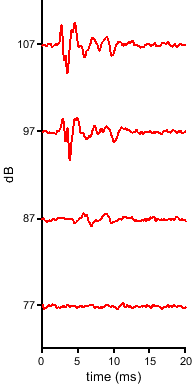

% pure tone 16 kHz plot

addpath('cjk-2018_11_12-P21_cx26tectacre_3');
tectaflCAP ={EPavg_p007,EPavg_p008,EPavg_p009,EPavg_p010};
figure
hold on
for x = 1:length(tectaflCAP)
    plot(tectaflCAP{1,x}.AverageData(:,1),tectaflCAP{1,x}.AverageData(:,4)-10*(x-1),'r', 'LineWidth',1.5)
end
dim = [2,4];
yticks([-30 -20 -10 0]);
yticklabels([77 87 97 107])
xlim([0 20]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);

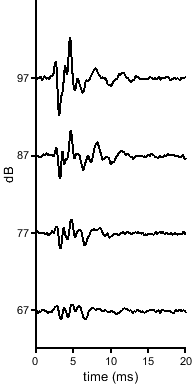

rmpath('cjk-2018_11_12-P21_cx26tectacre_3');

addpath('cjk-2019_10_31-P21_abr_tectacx26fl+_7');
flflCAP ={EPavg_p014,EPavg_p015,EPavg_p016,EPavg_p017};
figure
hold on
for x = 1:length(flflCAP)
    plot(flflCAP{1,x}.AverageData(:,1),flflCAP{1,x}.AverageData(:,4)-10*(x-1),'k','LineWidth',1.5)
end
dim = [2,4];
yticks([-30 -20 -10 0]);
yticklabels([67 77 87 97])
xlim([0 20]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);

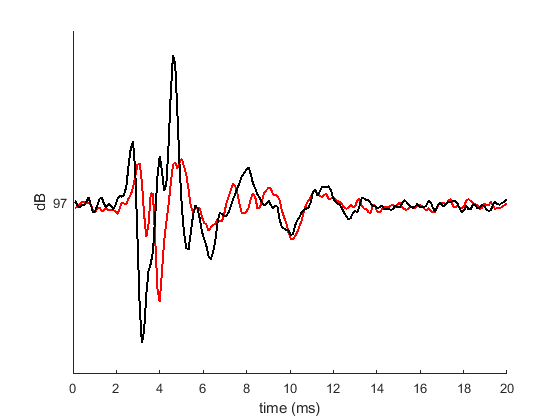


rmpath('cjk-2019_10_31-P21_abr_tectacx26fl+_7');


% same plot 

%97 dB, 16 kHz
addpath('cjk-2018_11_12-P21_cx26tectacre_3');
figure 
hold on
tectaflCAP = {EPavg_p008};
for x = 1:length(tectaflCAP)
    plot(tectaflCAP{1,x}.AverageData(:,1),tectaflCAP{1,x}.AverageData(:,4)-10*(x-1),'r', 'LineWidth',1.5)
end
dim = [2,4];
yticks([0]);
yticklabels([97])
xlim([0 20]);
xlabel('time (ms)');
ylabel('dB');
rmpath('cjk-2018_11_12-P21_cx26tectacre_3');
addpath('cjk-2019_10_31-P21_abr_tectacx26fl+_7');
flflCAP ={EPavg_p014};
for x = 1:length(flflCAP)
    plot(flflCAP{1,x}.AverageData(:,1),flflCAP{1,x}.AverageData(:,4)-10*(x-1),'k','LineWidth',1.5)
end

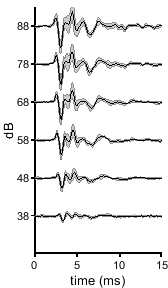

% average traces : click, 16 kHz 

% control (cx26 fl/fl)
addpath('cjk-2018_10_26-P21_cx26flfl_9');
flfl1 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2018_10_26-P21_cx26flfl_9');
addpath('cjk-2018_11_12-P21_cx26flfl_2');
flfl2 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2018_11_12-P21_cx26flfl_2')
addpath('cjk-2019_01_05-P21_cx26flfl_1');
flfl3 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_01_05-P21_cx26flfl_1')
addpath('cjk-2019_01_05-P21_cx26flfl_3');
flfl4 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_01_05-P21_cx26flfl_3')
addpath('cjk-2019_01_05-P21_cx26flfl_5');
flfl5 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_01_05-P21_cx26flfl_5')
addpath('cjk-2019_01_05-P21_cx26flfl_8');
flfl6 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_01_05-P21_cx26flfl_8')

meanflfl10 = mean([-(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))';(flfl4{1,1}.AverageData(:,4))';(flfl5{1,1}.AverageData(:,4))';(flfl6{1,1}.AverageData(:,4)+2)'],1);
meanflfl20 = mean([-(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))';(flfl4{1,2}.AverageData(:,4))';(flfl5{1,2}.AverageData(:,4))';(flfl6{1,2}.AverageData(:,4)+2)'],1);
meanflfl30 = mean([-(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))';(flfl4{1,3}.AverageData(:,4))';(flfl5{1,3}.AverageData(:,4))';(flfl6{1,3}.AverageData(:,4)+2)'],1);
meanflfl40 = mean([-(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))';(flfl4{1,4}.AverageData(:,4))';(flfl5{1,4}.AverageData(:,4))';(flfl6{1,4}.AverageData(:,4)+2)'],1);
meanflfl50 = mean([-(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))';(flfl4{1,5}.AverageData(:,4))';(flfl5{1,5}.AverageData(:,4))';(flfl6{1,5}.AverageData(:,4)+2)'],1);
meanflfl60 = mean([-(flfl1{1,6}.AverageData(:,4))';(flfl2{1,6}.AverageData(:,4))';(flfl3{1,6}.AverageData(:,4))';(flfl4{1,6}.AverageData(:,4))';(flfl5{1,6}.AverageData(:,4))';(flfl6{1,6}.AverageData(:,4)+2)'],1);

flflmean = {meanflfl10,meanflfl20,meanflfl30,meanflfl40,meanflfl50,meanflfl60};

stdflfl10 = std([-(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))';(flfl4{1,1}.AverageData(:,4))';(flfl5{1,1}.AverageData(:,4))';(flfl6{1,1}.AverageData(:,4)+2)'],1);
stdflfl20 = std([-(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))';(flfl4{1,2}.AverageData(:,4))';(flfl5{1,2}.AverageData(:,4))';(flfl6{1,2}.AverageData(:,4)+2)'],1);
stdflfl30 = std([-(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))';(flfl4{1,3}.AverageData(:,4))';(flfl5{1,3}.AverageData(:,4))';(flfl6{1,3}.AverageData(:,4)+2)'],1);
stdflfl40 = std([-(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))';(flfl4{1,4}.AverageData(:,4))';(flfl5{1,4}.AverageData(:,4))';(flfl6{1,4}.AverageData(:,4)+2)'],1);
stdflfl50 = std([-(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))';(flfl4{1,5}.AverageData(:,4))';(flfl5{1,5}.AverageData(:,4))';(flfl6{1,5}.AverageData(:,4)+2)'],1);
stdflfl60 = std([-(flfl1{1,6}.AverageData(:,4))';(flfl2{1,6}.AverageData(:,4))';(flfl3{1,6}.AverageData(:,4))';(flfl4{1,6}.AverageData(:,4))';(flfl5{1,6}.AverageData(:,4))';(flfl6{1,6}.AverageData(:,4)+2)'],1);

flflstd = {stdflfl10,stdflfl20,stdflfl30,stdflfl40,stdflfl50,stdflfl60};


figure
hold on
for x = 1:length(flflmean)
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),flflstd{1,x})
end
dim =[1.75,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([-50 -40 -30 -20 -10 0]);
yticklabels([38 48 58 68 78 88])
ylim([-60 5])
hold off

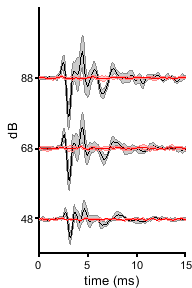


% cko clicks
addpath('cjk-2018_10_26-P21_Cx26flfl_tecta8');
cko1 ={EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p002};
rmpath('cjk-2018_10_26-P21_Cx26flfl_tecta8');
addpath('cjk-2018_10_26-P21_cx26flfl_tecta_7');
cko2 ={EPavg_p003,EPavg_p002};
rmpath('cjk-2018_10_26-P21_cx26flfl_tecta_7');
addpath('cjk-2018_11_12-P21_cx26tectacre_3');
cko3 ={EPavg_p003,EPavg_p002};
rmpath('cjk-2018_11_12-P21_cx26tectacre_3');
addpath('cjk-2019_01_05-P21_tectacx26flfl_2');
cko4 ={EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p002};
rmpath('cjk-2019_01_05-P21_tectacx26flfl_2');
addpath('cjk-2019_10_07-P21_abr_tectacx26flfl_3');
cko5 ={EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008,EPavg_p003};
rmpath('cjk-2019_10_07-P21_abr_tectacx26flfl_3');
addpath('cjk-2019_10_07-P21_abr_tectacx26flfl_6');
cko6 ={EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008,EPavg_p003};
rmpath('cjk-2019_10_07-P21_abr_tectacx26flfl_6');
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_4');
cko7 ={EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008,EPavg_p003};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_4');

meancko0 = mean([-(cko1{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))';(-cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko5{1,7}.AverageData(:,4))';(cko6{1,7}.AverageData(:,4))';(cko7{1,7}.AverageData(:,4))'],1);
meancko10 = mean([-(cko1{1,1}.AverageData(:,4))';(-cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))';(cko5{1,1}.AverageData(:,4))';(cko6{1,1}.AverageData(:,4))';(cko7{1,1}.AverageData(:,4))'],1);
meancko20 = mean([-(cko1{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))';(cko5{1,2}.AverageData(:,4))';(cko6{1,2}.AverageData(:,4))';(cko7{1,2}.AverageData(:,4))'],1);
meancko30 = mean([-(cko1{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))';(cko5{1,3}.AverageData(:,4))';(cko6{1,3}.AverageData(:,4))';(cko7{1,3}.AverageData(:,4))'],1);
meancko40 = mean([(cko5{1,4}.AverageData(:,4))';(cko6{1,4}.AverageData(:,4))';(cko7{1,4}.AverageData(:,4))'],1);
meancko50 = mean([(cko5{1,5}.AverageData(:,4))';(cko6{1,5}.AverageData(:,4))';(cko7{1,5}.AverageData(:,4))'],1);
meancko60 = mean([(cko5{1,6}.AverageData(:,4))';(cko6{1,6}.AverageData(:,4))';(cko7{1,6}.AverageData(:,4))'],1);

ckomean = {meancko10,meancko20,meancko30,meancko40,meancko50,meancko60};
stdcko0 = std([-(cko1{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))';-(cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko5{1,7}.AverageData(:,4))';(cko6{1,7}.AverageData(:,4))';(cko7{1,7}.AverageData(:,4))'],1);
stdcko10 = std([-(cko1{1,1}.AverageData(:,4))';-(cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))';(cko5{1,1}.AverageData(:,4))';(cko6{1,1}.AverageData(:,4))';(cko7{1,1}.AverageData(:,4))'],1);
stdcko20 = std([-(cko1{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))';(cko5{1,2}.AverageData(:,4))';(cko6{1,2}.AverageData(:,4))';(cko7{1,2}.AverageData(:,4))'],1);
stdcko30 = std([-(cko1{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))';(cko5{1,3}.AverageData(:,4))';(cko6{1,3}.AverageData(:,4))';(cko7{1,3}.AverageData(:,4))'],1);
stdcko40 = std([(cko5{1,4}.AverageData(:,4))';(cko6{1,4}.AverageData(:,4))';(cko7{1,4}.AverageData(:,4))'],1);
stdcko50 = std([(cko5{1,5}.AverageData(:,4))';(cko6{1,5}.AverageData(:,4))';(cko7{1,5}.AverageData(:,4))'],1);
stdcko60 = std([(cko5{1,6}.AverageData(:,4))';(cko6{1,6}.AverageData(:,4))';(cko7{1,6}.AverageData(:,4))'],1);

stdcko = {stdcko10,stdcko20,stdcko30,stdcko40,stdcko50,stdcko60};

figure
hold on
for x = 1:2:5
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-5*(x-1),flflstd{1,x})
end
for x = 1:2:5
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(cko1{1,1}.AverageData(:,1),ckomean{1,x}-5*(x-1),stdcko{1,x},'lineprops','r')
end
dim =[2,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([ -20 -10 0]);
yticklabels([ 48 68 88])
ylim([-25 10])
hold off
%print(gcf,'-dpdf')

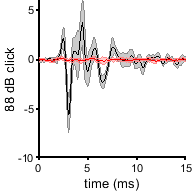


% compare only 88 dB click trace
figure
hold on
shadedErrorBar(flfl1{1,1}.AverageData(:,1)',meanflfl10,stdflfl10)
shadedErrorBar(flfl1{1,1}.AverageData(:,1)',meancko10,stdcko10,'lineprops','r')
xlim([0 15]);
dim = [2 2];
xlabel('time (ms)');
ylabel('88 dB click');
handle = gcf;
figQuality(gcf,gca,dim);

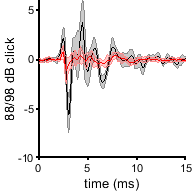


% 88 db click control to 98 dB click cko
figure
hold on
shadedErrorBar(flfl1{1,1}.AverageData(:,1)',meanflfl10,stdflfl10)
shadedErrorBar(flfl1{1,1}.AverageData(:,1)',meancko0,stdcko0,'lineprops','r')
xlim([0 15]);
dim = [2 2];
xlabel('time (ms)');
ylabel('88/98 dB click');
handle = gcf;
figQuality(gcf,gca,dim);

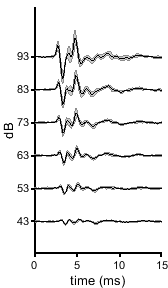


% 16 kHz pure tone comparison - waterfall and individual plots 

addpath('cjk-2018_10_26-P21_cx26flfl_9');
flfl1 ={EPavg_p021,EPavg_p022,EPavg_p023,EPavg_p024,EPavg_p025,EPavg_p026};
rmpath('cjk-2018_10_26-P21_cx26flfl_9');
addpath('cjk-2018_11_12-P21_cx26flfl_2');
flfl2 ={EPavg_p038,EPavg_p039,EPavg_p040,EPavg_p041,EPavg_p042,EPavg_p043};
rmpath('cjk-2018_11_12-P21_cx26flfl_2')
addpath('cjk-2019_01_05-P21_cx26flfl_1');
flfl3 ={EPavg_p044,EPavg_p045,EPavg_p046,EPavg_p047,EPavg_p048,EPavg_p049};
rmpath('cjk-2019_01_05-P21_cx26flfl_1')
addpath('cjk-2019_01_05-P21_cx26flfl_3');
flfl4 = {EPavg_p033,EPavg_p034,EPavg_p035,EPavg_p036,EPavg_p037,EPavg_p038};
rmpath('cjk-2019_01_05-P21_cx26flfl_3')
addpath('cjk-2019_01_05-P21_cx26flfl_5');
flfl5 ={EPavg_p033,EPavg_p034,EPavg_p035,EPavg_p036,EPavg_p037,EPavg_p038};
rmpath('cjk-2019_01_05-P21_cx26flfl_5')
addpath('cjk-2019_01_05-P21_cx26flfl_8');
flfl6 ={EPavg_p012,EPavg_p013,EPavg_p014,EPavg_p015,EPavg_p016,EPavg_p017};
rmpath('cjk-2019_01_05-P21_cx26flfl_8')

meanflfl10 = mean([-(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))';(flfl4{1,1}.AverageData(:,4))';(flfl5{1,1}.AverageData(:,4))';(flfl6{1,1}.AverageData(:,4)+2)'],1);
meanflfl20 = mean([-(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))';(flfl4{1,2}.AverageData(:,4))';(flfl5{1,2}.AverageData(:,4))';(flfl6{1,2}.AverageData(:,4)+2)'],1);
meanflfl30 = mean([-(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))';(flfl4{1,3}.AverageData(:,4))';(flfl5{1,3}.AverageData(:,4))';(flfl6{1,3}.AverageData(:,4)+2)'],1);
meanflfl40 = mean([-(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))';(flfl4{1,4}.AverageData(:,4))';(flfl5{1,4}.AverageData(:,4))';(flfl6{1,4}.AverageData(:,4)+2)'],1);
meanflfl50 = mean([-(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))';(flfl4{1,5}.AverageData(:,4))';(flfl5{1,5}.AverageData(:,4))';(flfl6{1,5}.AverageData(:,4)+2)'],1);
meanflfl60 = mean([-(flfl1{1,6}.AverageData(:,4))';(flfl2{1,6}.AverageData(:,4))';(flfl3{1,6}.AverageData(:,4))';(flfl4{1,6}.AverageData(:,4))';(flfl5{1,6}.AverageData(:,4))';(flfl6{1,6}.AverageData(:,4)+2)'],1);

flflmean = {meanflfl10,meanflfl20,meanflfl30,meanflfl40,meanflfl50,meanflfl60};

stdflfl10 = std([-(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))';(flfl4{1,1}.AverageData(:,4))';(flfl5{1,1}.AverageData(:,4))';(flfl6{1,1}.AverageData(:,4)+2)'],1);
stdflfl20 = std([-(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))';(flfl4{1,2}.AverageData(:,4))';(flfl5{1,2}.AverageData(:,4))';(flfl6{1,2}.AverageData(:,4)+2)'],1);
stdflfl30 = std([-(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))';(flfl4{1,3}.AverageData(:,4))';(flfl5{1,3}.AverageData(:,4))';(flfl6{1,3}.AverageData(:,4)+2)'],1);
stdflfl40 = std([-(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))';(flfl4{1,4}.AverageData(:,4))';(flfl5{1,4}.AverageData(:,4))';(flfl6{1,4}.AverageData(:,4)+2)'],1);
stdflfl50 = std([-(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))';(flfl4{1,5}.AverageData(:,4))';(flfl5{1,5}.AverageData(:,4))';(flfl6{1,5}.AverageData(:,4)+2)'],1);
stdflfl60 = std([-(flfl1{1,6}.AverageData(:,4))';(flfl2{1,6}.AverageData(:,4))';(flfl3{1,6}.AverageData(:,4))';(flfl4{1,6}.AverageData(:,4))';(flfl5{1,6}.AverageData(:,4))';(flfl6{1,6}.AverageData(:,4)+2)'],1);

flflstd = {stdflfl10,stdflfl20,stdflfl30,stdflfl40,stdflfl50,stdflfl60};


figure
hold on
for x = 1:length(flflmean)
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),flflstd{1,x})
end
dim =[1.75,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([-50 -40 -30 -20 -10 0]);
yticklabels([43 53 63 73 83 93])
ylim([-60 15])
hold off

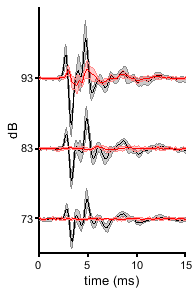


% cko 16 kHz 

addpath('cjk-2018_10_26-P21_Cx26flfl_tecta8');
cko1 ={EPavg_p012,EPavg_p014,EPavg_p015,EPavg_p016};
rmpath('cjk-2018_10_26-P21_Cx26flfl_tecta8');
addpath('cjk-2018_10_26-P21_cx26flfl_tecta_7');
cko2 ={EPavg_p011,EPavg_p012,EPavg_p013,EPavg_p014};
rmpath('cjk-2018_10_26-P21_cx26flfl_tecta_7');
addpath('cjk-2018_11_12-P21_cx26tectacre_3');
cko3 ={EPavg_p007,EPavg_p008,EPavg_p009,EPavg_p010};
rmpath('cjk-2018_11_12-P21_cx26tectacre_3');
addpath('cjk-2019_01_05-P21_tectacx26flfl_2');
cko4 ={EPavg_p008,EPavg_p009,EPavg_p010,EPavg_p011};
rmpath('cjk-2019_01_05-P21_tectacx26flfl_2');
addpath('cjk-2019_10_07-P21_abr_tectacx26flfl_3');
cko5 ={EPavg_p018,EPavg_p019,EPavg_p020};
rmpath('cjk-2019_10_07-P21_abr_tectacx26flfl_3');
addpath('cjk-2019_10_07-P21_abr_tectacx26flfl_6');
cko6 ={EPavg_p020,EPavg_p021,EPavg_p022,EPavg_p023};
rmpath('cjk-2019_10_07-P21_abr_tectacx26flfl_6');
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_4');
cko7 ={EPavg_p020,EPavg_p021,EPavg_p022};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_4');

%meancko0 = mean([(-cko1{1,1}.AverageData(:,4))';(-cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))';(cko5{1,1}.AverageData(:,4))';(cko6{1,1}.AverageData(:,4))';(cko7{1,1}.AverageData(:,4))'],1);
meancko10 = mean([(-cko1{1,2}.AverageData(:,4))';(-cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))';(cko5{1,2}.AverageData(:,4))';(cko6{1,2}.AverageData(:,4))';(cko7{1,2}.AverageData(:,4))'],1);
meancko20 = mean([(-cko1{1,3}.AverageData(:,4))';(-cko2{1,3}.AverageData(:,4))';(cko3{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))';(cko5{1,3}.AverageData(:,4))';(cko6{1,3}.AverageData(:,4))';(cko7{1,3}.AverageData(:,4))'],1);
meancko30 = mean([(-cko1{1,4}.AverageData(:,4))';(-cko2{1,4}.AverageData(:,4))';(cko3{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))';(cko6{1,4}.AverageData(:,4))'],1);

ckomean = {meancko10,meancko20,meancko30};

%stdcko0 = std([(-cko1{1,1}.AverageData(:,4))';(-cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))';(cko5{1,1}.AverageData(:,4))';(cko6{1,1}.AverageData(:,4))';(cko7{1,1}.AverageData(:,4))'],1);
stdcko10 = std([(-cko1{1,2}.AverageData(:,4))';(-cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))';(cko5{1,2}.AverageData(:,4))';(cko6{1,2}.AverageData(:,4))';(cko7{1,2}.AverageData(:,4))'],1);
stdcko20 = std([(-cko1{1,3}.AverageData(:,4))';(-cko2{1,3}.AverageData(:,4))';(cko3{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))';(cko5{1,3}.AverageData(:,4))';(cko6{1,3}.AverageData(:,4))';(cko7{1,3}.AverageData(:,4))'],1);
stdcko30 = std([(-cko1{1,4}.AverageData(:,4))';(-cko2{1,4}.AverageData(:,4))';(cko3{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))';(cko6{1,4}.AverageData(:,4))'],1);

stdcko = {stdcko10,stdcko20,stdcko30};

figure
hold on
for x = 1:3
shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),flflstd{1,x})
end
for x = 1:3
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(cko1{1,1}.AverageData(:,1),ckomean{1,x}-10*(x-1),stdcko{1,x},'lineprops','r')
    
end
dim =[2,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([ -20 -10 0]);
yticklabels([73 83 93])
ylim([-25 10])
hold off
print(gcf,'-dpdf')

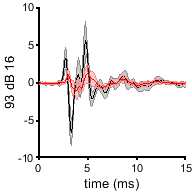


% compare 93db 16 kHz 
figure
hold on
shadedErrorBar(flfl1{1,1}.AverageData(:,1)',meanflfl10,stdflfl10)
shadedErrorBar(flfl1{1,1}.AverageData(:,1)',meancko10,stdcko10,'lineprops','r')
xlim([0 15]);
dim = [2 2];
xlabel('time (ms)');
ylabel('93 dB 16');
handle = gcf;
figQuality(gcf,gca,dim);

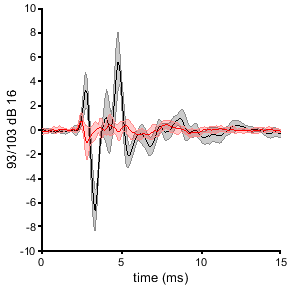


% 93 db 16 control to 103 dB 16 cko
figure
hold on
shadedErrorBar(flfl1{1,1}.AverageData(:,1)',meanflfl10,stdflfl10)
shadedErrorBar(flfl1{1,1}.AverageData(:,1)',meancko0,stdcko0,'lineprops','r')
xlim([0 15]);
dim = [3 3];
xlabel('time (ms)');
ylabel('93/103 dB 16');
handle = gcf;
figQuality(gcf,gca,dim);

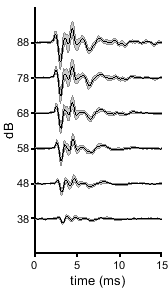

% grouping together P21 gcamp+ and gcamp- animals

% average traces : click, 16 kHz 

% control (cx26 fl/fl)
addpath('cjk-2018_10_26-P21_cx26flfl_9');
flfl1 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2018_10_26-P21_cx26flfl_9');
addpath('cjk-2018_11_12-P21_cx26flfl_2');
flfl2 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2018_11_12-P21_cx26flfl_2')
addpath('cjk-2019_01_05-P21_cx26flfl_1');
flfl3 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_01_05-P21_cx26flfl_1')
addpath('cjk-2019_01_05-P21_cx26flfl_3');
flfl4 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_01_05-P21_cx26flfl_3')
addpath('cjk-2019_01_05-P21_cx26flfl_5');
flfl5 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_01_05-P21_cx26flfl_5')
addpath('cjk-2019_01_05-P21_cx26flfl_8');
flfl6 ={EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_01_05-P21_cx26flfl_8')
addpath('cjk-2019_10_07-P21_abr_cx26flfl_gcamp6_1');
flfl7 = {EPavg_p002,EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_10_07-P21_abr_cx26flfl_gcamp6_1')
addpath('cjk-2019_10_07-P21_abr_cx26flfl_gcamp6_7');
flfl8 = {EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008};
rmpath('cjk-2019_10_07-P21_abr_cx26flfl_gcamp6_7');
addpath('cjk-2019_10_31-P21_abr_cx26flfl_gcamp6_2');
flfl9 = {EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008};
rmpath('cjk-2019_10_31-P21_abr_cx26flfl_gcamp6_2');

meanflfl10 = mean([-(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))';(flfl4{1,1}.AverageData(:,4))';(flfl5{1,1}.AverageData(:,4))';(flfl6{1,1}.AverageData(:,4)+2)';(flfl7{1,1}.AverageData(:,4))';(flfl8{1,1}.AverageData(:,4))';(flfl9{1,1}.AverageData(:,4))'],1);
meanflfl20 = mean([-(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))';(flfl4{1,2}.AverageData(:,4))';(flfl5{1,2}.AverageData(:,4))';(flfl6{1,2}.AverageData(:,4)+2)';(flfl7{1,2}.AverageData(:,4))';(flfl8{1,2}.AverageData(:,4))';(flfl9{1,2}.AverageData(:,4))'],1);
meanflfl30 = mean([-(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))';(flfl4{1,3}.AverageData(:,4))';(flfl5{1,3}.AverageData(:,4))';(flfl6{1,3}.AverageData(:,4)+2)';(flfl7{1,3}.AverageData(:,4))';(flfl8{1,3}.AverageData(:,4))';(flfl9{1,3}.AverageData(:,4))'],1);
meanflfl40 = mean([-(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))';(flfl4{1,4}.AverageData(:,4))';(flfl5{1,4}.AverageData(:,4))';(flfl6{1,4}.AverageData(:,4)+2)';(flfl7{1,4}.AverageData(:,4))';(flfl8{1,4}.AverageData(:,4))';(flfl9{1,4}.AverageData(:,4))'],1);
meanflfl50 = mean([-(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))';(flfl4{1,5}.AverageData(:,4))';(flfl5{1,5}.AverageData(:,4))';(flfl6{1,5}.AverageData(:,4)+2)';(flfl7{1,5}.AverageData(:,4))';(flfl8{1,5}.AverageData(:,4))';(flfl9{1,5}.AverageData(:,4))'],1);
meanflfl60 = mean([-(flfl1{1,6}.AverageData(:,4))';(flfl2{1,6}.AverageData(:,4))';(flfl3{1,6}.AverageData(:,4))';(flfl4{1,6}.AverageData(:,4))';(flfl5{1,6}.AverageData(:,4))';(flfl6{1,6}.AverageData(:,4)+2)';(flfl7{1,6}.AverageData(:,4))';(flfl8{1,6}.AverageData(:,4))';(flfl9{1,6}.AverageData(:,4))'],1);

flflmean = {meanflfl10,meanflfl20,meanflfl30,meanflfl40,meanflfl50,meanflfl60};

stdflfl10 = std([-(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))';(flfl4{1,1}.AverageData(:,4))';(flfl5{1,1}.AverageData(:,4))';(flfl6{1,1}.AverageData(:,4)+2)';(flfl7{1,1}.AverageData(:,4))';(flfl8{1,1}.AverageData(:,4))';(flfl9{1,1}.AverageData(:,4))'],1);
stdflfl20 = std([-(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))';(flfl4{1,2}.AverageData(:,4))';(flfl5{1,2}.AverageData(:,4))';(flfl6{1,2}.AverageData(:,4)+2)';(flfl7{1,2}.AverageData(:,4))';(flfl8{1,2}.AverageData(:,4))';(flfl9{1,2}.AverageData(:,4))'],1);
stdflfl30 = std([-(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))';(flfl4{1,3}.AverageData(:,4))';(flfl5{1,3}.AverageData(:,4))';(flfl6{1,3}.AverageData(:,4)+2)';(flfl7{1,3}.AverageData(:,4))';(flfl8{1,3}.AverageData(:,4))';(flfl9{1,3}.AverageData(:,4))'],1);
stdflfl40 = std([-(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))';(flfl4{1,4}.AverageData(:,4))';(flfl5{1,4}.AverageData(:,4))';(flfl6{1,4}.AverageData(:,4)+2)';(flfl7{1,4}.AverageData(:,4))';(flfl8{1,4}.AverageData(:,4))';(flfl9{1,4}.AverageData(:,4))'],1);
stdflfl50 = std([-(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))';(flfl4{1,5}.AverageData(:,4))';(flfl5{1,5}.AverageData(:,4))';(flfl6{1,5}.AverageData(:,4)+2)';(flfl7{1,5}.AverageData(:,4))';(flfl8{1,5}.AverageData(:,4))';(flfl9{1,5}.AverageData(:,4))'],1);
stdflfl60 = std([-(flfl1{1,6}.AverageData(:,4))';(flfl2{1,6}.AverageData(:,4))';(flfl3{1,6}.AverageData(:,4))';(flfl4{1,6}.AverageData(:,4))';(flfl5{1,6}.AverageData(:,4))';(flfl6{1,6}.AverageData(:,4)+2)';(flfl7{1,6}.AverageData(:,4))';(flfl8{1,6}.AverageData(:,4))';(flfl9{1,6}.AverageData(:,4))'],1);

flflstd = {stdflfl10,stdflfl20,stdflfl30,stdflfl40,stdflfl50,stdflfl60};


figure
hold on
for x = 1:length(flflmean)
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),flflstd{1,x})
end
dim =[1.75,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([-50 -40 -30 -20 -10 0]);
yticklabels([38 48 58 68 78 88])
ylim([-60 10])
hold off

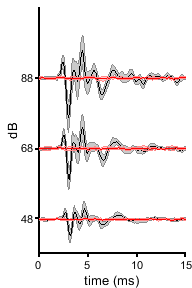


% cko clicks
addpath('cjk-2018_10_26-P21_Cx26flfl_tecta8');
cko1 ={EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p002};
rmpath('cjk-2018_10_26-P21_Cx26flfl_tecta8');
addpath('cjk-2018_10_26-P21_cx26flfl_tecta_7');
cko2 ={EPavg_p003,EPavg_p002};
rmpath('cjk-2018_10_26-P21_cx26flfl_tecta_7');
addpath('cjk-2018_11_12-P21_cx26tectacre_3');
cko3 ={EPavg_p003,EPavg_p002};
rmpath('cjk-2018_11_12-P21_cx26tectacre_3');
addpath('cjk-2019_01_05-P21_tectacx26flfl_2');
cko4 ={EPavg_p003,EPavg_p004,EPavg_p005,EPavg_p002};
rmpath('cjk-2019_01_05-P21_tectacx26flfl_2');
addpath('cjk-2019_10_07-P21_abr_tectacx26flfl_3');
cko5 ={EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008,EPavg_p003};
rmpath('cjk-2019_10_07-P21_abr_tectacx26flfl_3');
addpath('cjk-2019_10_07-P21_abr_tectacx26flfl_6');
cko6 ={EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008,EPavg_p003};
rmpath('cjk-2019_10_07-P21_abr_tectacx26flfl_6');
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_4');
cko7 ={EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008,EPavg_p003};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_4');
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_1');
cko8 = {EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_1')
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_3');
cko9 = {EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_3');
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_5');
cko10 = {EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_5');
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_6');
cko11 = {EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007,EPavg_p008};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_6');

meancko0 = mean([-(cko1{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))';(-cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko5{1,7}.AverageData(:,4))';(cko6{1,7}.AverageData(:,4))';(cko7{1,7}.AverageData(:,4))'],1);
meancko10 = mean([-(cko1{1,1}.AverageData(:,4))';(-cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))';(cko5{1,1}.AverageData(:,4))';(cko6{1,1}.AverageData(:,4))';(cko7{1,1}.AverageData(:,4))';(cko8{1,1}.AverageData(:,4))';(cko9{1,1}.AverageData(:,4))';(cko10{1,1}.AverageData(:,4))';(cko11{1,1}.AverageData(:,4))'],1);
meancko20 = mean([-(cko1{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))';(cko5{1,2}.AverageData(:,4))';(cko6{1,2}.AverageData(:,4))';(cko7{1,2}.AverageData(:,4))';(cko8{1,2}.AverageData(:,4))';(cko9{1,2}.AverageData(:,4))';(cko10{1,2}.AverageData(:,4))';(cko11{1,2}.AverageData(:,4))'],1);
meancko30 = mean([-(cko1{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))';(cko5{1,3}.AverageData(:,4))';(cko6{1,3}.AverageData(:,4))';(cko7{1,3}.AverageData(:,4))';(cko8{1,3}.AverageData(:,4))';(cko9{1,3}.AverageData(:,4))';(cko10{1,3}.AverageData(:,4))';(cko11{1,3}.AverageData(:,4))'],1);
meancko40 = mean([(cko5{1,4}.AverageData(:,4))';(cko6{1,4}.AverageData(:,4))';(cko7{1,4}.AverageData(:,4))';(cko8{1,4}.AverageData(:,4))';(cko9{1,4}.AverageData(:,4))';(cko10{1,4}.AverageData(:,4))';(cko11{1,4}.AverageData(:,4))'],1);
meancko50 = mean([(cko5{1,5}.AverageData(:,4))';(cko6{1,5}.AverageData(:,4))';(cko7{1,5}.AverageData(:,4))';(cko8{1,5}.AverageData(:,4))';(cko9{1,5}.AverageData(:,4))';(cko10{1,5}.AverageData(:,4))';(cko11{1,5}.AverageData(:,4))'],1);
meancko60 = mean([(cko5{1,6}.AverageData(:,4))';(cko6{1,6}.AverageData(:,4))';(cko7{1,6}.AverageData(:,4))';(cko8{1,6}.AverageData(:,4))';(cko9{1,6}.AverageData(:,4))';(cko10{1,6}.AverageData(:,4))';(cko11{1,6}.AverageData(:,4))'],1);

ckomean = {meancko10,meancko20,meancko30,meancko40,meancko50,meancko60};
stdcko0 = std([-(cko1{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))';-(cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko5{1,7}.AverageData(:,4))';(cko6{1,7}.AverageData(:,4))';(cko7{1,7}.AverageData(:,4))'],1);
stdcko10 = std([-(cko1{1,1}.AverageData(:,4))';-(cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))';(cko5{1,1}.AverageData(:,4))';(cko6{1,1}.AverageData(:,4))';(cko7{1,1}.AverageData(:,4))';(cko8{1,1}.AverageData(:,4))';(cko9{1,1}.AverageData(:,4))';(cko10{1,1}.AverageData(:,4))';(cko11{1,1}.AverageData(:,4))'],1);
stdcko20 = std([-(cko1{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))';(cko5{1,2}.AverageData(:,4))';(cko6{1,2}.AverageData(:,4))';(cko7{1,2}.AverageData(:,4))';(cko8{1,2}.AverageData(:,4))';(cko9{1,2}.AverageData(:,4))';(cko10{1,2}.AverageData(:,4))';(cko11{1,3}.AverageData(:,4))'],1);
stdcko30 = std([-(cko1{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))';(cko5{1,3}.AverageData(:,4))';(cko6{1,3}.AverageData(:,4))';(cko7{1,3}.AverageData(:,4))';(cko8{1,3}.AverageData(:,4))';(cko9{1,3}.AverageData(:,4))';(cko10{1,3}.AverageData(:,4))';(cko11{1,3}.AverageData(:,4))'],1);
stdcko40 = std([(cko5{1,4}.AverageData(:,4))';(cko6{1,4}.AverageData(:,4))';(cko7{1,4}.AverageData(:,4))';(cko8{1,4}.AverageData(:,4))';(cko9{1,4}.AverageData(:,4))';(cko10{1,4}.AverageData(:,4))';(cko11{1,4}.AverageData(:,4))'],1);
stdcko50 = std([(cko5{1,5}.AverageData(:,4))';(cko6{1,5}.AverageData(:,4))';(cko7{1,5}.AverageData(:,4))';(cko8{1,5}.AverageData(:,4))';(cko9{1,5}.AverageData(:,4))';(cko10{1,5}.AverageData(:,4))';(cko11{1,5}.AverageData(:,4))'],1);
stdcko60 = std([(cko5{1,6}.AverageData(:,4))';(cko6{1,6}.AverageData(:,4))';(cko7{1,6}.AverageData(:,4))';(cko8{1,6}.AverageData(:,4))';(cko9{1,6}.AverageData(:,4))';(cko10{1,6}.AverageData(:,4))';(cko11{1,6}.AverageData(:,4))'],1);

stdcko = {stdcko10,stdcko20,stdcko30,stdcko40,stdcko50,stdcko60};

figure
hold on
for x = 1:2:5
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-5*(x-1),flflstd{1,x})
end
for x = 1:2:5
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(cko1{1,1}.AverageData(:,1),ckomean{1,x}-5*(x-1),stdcko{1,x},'lineprops','r')
end
dim =[2,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([ -20 -10 0]);
yticklabels([ 48 68 88])
ylim([-25 10])
hold off

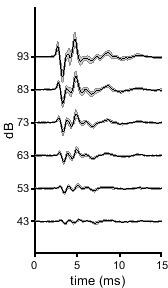


% 16 kHz 
addpath('cjk-2018_10_26-P21_cx26flfl_9');
flfl1 ={EPavg_p021,EPavg_p022,EPavg_p023,EPavg_p024,EPavg_p025,EPavg_p026};
rmpath('cjk-2018_10_26-P21_cx26flfl_9');
addpath('cjk-2018_11_12-P21_cx26flfl_2');
flfl2 ={EPavg_p038,EPavg_p039,EPavg_p040,EPavg_p041,EPavg_p042,EPavg_p043};
rmpath('cjk-2018_11_12-P21_cx26flfl_2')
addpath('cjk-2019_01_05-P21_cx26flfl_1');
flfl3 ={EPavg_p044,EPavg_p045,EPavg_p046,EPavg_p047,EPavg_p048,EPavg_p049};
rmpath('cjk-2019_01_05-P21_cx26flfl_1')
addpath('cjk-2019_01_05-P21_cx26flfl_3');
flfl4 = {EPavg_p033,EPavg_p034,EPavg_p035,EPavg_p036,EPavg_p037,EPavg_p038};
rmpath('cjk-2019_01_05-P21_cx26flfl_3')
addpath('cjk-2019_01_05-P21_cx26flfl_5');
flfl5 ={EPavg_p033,EPavg_p034,EPavg_p035,EPavg_p036,EPavg_p037,EPavg_p038};
rmpath('cjk-2019_01_05-P21_cx26flfl_5')
addpath('cjk-2019_01_05-P21_cx26flfl_8');
flfl6 ={EPavg_p012,EPavg_p013,EPavg_p014,EPavg_p015,EPavg_p016,EPavg_p017};
rmpath('cjk-2019_01_05-P21_cx26flfl_8')
addpath('cjk-2019_10_07-P21_abr_cx26flfl_gcamp6_1');
flfl7 = {EPavg_p021,EPavg_p022,EPavg_p023,EPavg_p024,EPavg_p025,EPavg_p026};
rmpath('cjk-2019_10_07-P21_abr_cx26flfl_gcamp6_1')
addpath('cjk-2019_10_07-P21_abr_cx26flfl_gcamp6_7');
flfl8 = {EPavg_p040,EPavg_p041,EPavg_p042,EPavg_p043,EPavg_p044,EPavg_p045};
rmpath('cjk-2019_10_07-P21_abr_cx26flfl_gcamp6_7');
addpath('cjk-2019_10_31-P21_abr_cx26flfl_gcamp6_2');
flfl9 = {EPavg_p042,EPavg_p043,EPavg_p044,EPavg_p045,EPavg_p046,EPavg_p047};
rmpath('cjk-2019_10_31-P21_abr_cx26flfl_gcamp6_2');

meanflfl10 = mean([-(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))';(flfl4{1,1}.AverageData(:,4))';(flfl5{1,1}.AverageData(:,4))';(flfl6{1,1}.AverageData(:,4)+2)';(flfl7{1,1}.AverageData(:,4))';(flfl8{1,1}.AverageData(:,4))';(flfl9{1,1}.AverageData(:,4))'],1);
meanflfl20 = mean([-(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))';(flfl4{1,2}.AverageData(:,4))';(flfl5{1,2}.AverageData(:,4))';(flfl6{1,2}.AverageData(:,4)+2)';(flfl7{1,2}.AverageData(:,4))';(flfl8{1,2}.AverageData(:,4))';(flfl9{1,2}.AverageData(:,4))'],1);
meanflfl30 = mean([-(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))';(flfl4{1,3}.AverageData(:,4))';(flfl5{1,3}.AverageData(:,4))';(flfl6{1,3}.AverageData(:,4)+2)';(flfl7{1,3}.AverageData(:,4))';(flfl8{1,3}.AverageData(:,4))';(flfl9{1,3}.AverageData(:,4))'],1);
meanflfl40 = mean([-(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))';(flfl4{1,4}.AverageData(:,4))';(flfl5{1,4}.AverageData(:,4))';(flfl6{1,4}.AverageData(:,4)+2)';(flfl7{1,4}.AverageData(:,4))';(flfl8{1,4}.AverageData(:,4))';(flfl9{1,4}.AverageData(:,4))'],1);
meanflfl50 = mean([-(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))';(flfl4{1,5}.AverageData(:,4))';(flfl5{1,5}.AverageData(:,4))';(flfl6{1,5}.AverageData(:,4)+2)';(flfl7{1,5}.AverageData(:,4))';(flfl8{1,5}.AverageData(:,4))';(flfl9{1,5}.AverageData(:,4))'],1);
meanflfl60 = mean([-(flfl1{1,6}.AverageData(:,4))';(flfl2{1,6}.AverageData(:,4))';(flfl3{1,6}.AverageData(:,4))';(flfl4{1,6}.AverageData(:,4))';(flfl5{1,6}.AverageData(:,4))';(flfl6{1,6}.AverageData(:,4)+2)';(flfl7{1,6}.AverageData(:,4))';(flfl8{1,6}.AverageData(:,4))';(flfl9{1,6}.AverageData(:,4))'],1);

flflmean = {meanflfl10,meanflfl20,meanflfl30,meanflfl40,meanflfl50,meanflfl60};

stdflfl10 = std([-(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))';(flfl4{1,1}.AverageData(:,4))';(flfl5{1,1}.AverageData(:,4))';(flfl6{1,1}.AverageData(:,4)+2)';(flfl7{1,1}.AverageData(:,4))';(flfl8{1,1}.AverageData(:,4))';(flfl9{1,1}.AverageData(:,4))'],1);
stdflfl20 = std([-(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))';(flfl4{1,2}.AverageData(:,4))';(flfl5{1,2}.AverageData(:,4))';(flfl6{1,2}.AverageData(:,4)+2)';(flfl7{1,2}.AverageData(:,4))';(flfl8{1,2}.AverageData(:,4))';(flfl9{1,2}.AverageData(:,4))'],1);
stdflfl30 = std([-(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))';(flfl4{1,3}.AverageData(:,4))';(flfl5{1,3}.AverageData(:,4))';(flfl6{1,3}.AverageData(:,4)+2)';(flfl7{1,3}.AverageData(:,4))';(flfl8{1,3}.AverageData(:,4))';(flfl9{1,3}.AverageData(:,4))'],1);
stdflfl40 = std([-(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))';(flfl4{1,4}.AverageData(:,4))';(flfl5{1,4}.AverageData(:,4))';(flfl6{1,4}.AverageData(:,4)+2)';(flfl7{1,4}.AverageData(:,4))';(flfl8{1,4}.AverageData(:,4))';(flfl9{1,4}.AverageData(:,4))'],1);
stdflfl50 = std([-(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))';(flfl4{1,5}.AverageData(:,4))';(flfl5{1,5}.AverageData(:,4))';(flfl6{1,5}.AverageData(:,4)+2)';(flfl7{1,5}.AverageData(:,4))';(flfl8{1,5}.AverageData(:,4))';(flfl9{1,5}.AverageData(:,4))'],1);
stdflfl60 = std([-(flfl1{1,6}.AverageData(:,4))';(flfl2{1,6}.AverageData(:,4))';(flfl3{1,6}.AverageData(:,4))';(flfl4{1,6}.AverageData(:,4))';(flfl5{1,6}.AverageData(:,4))';(flfl6{1,6}.AverageData(:,4)+2)';(flfl7{1,6}.AverageData(:,4))';(flfl8{1,6}.AverageData(:,4))';(flfl9{1,6}.AverageData(:,4))'],1);

flflstd = {stdflfl10,stdflfl20,stdflfl30,stdflfl40,stdflfl50,stdflfl60};


figure
hold on
for x = 1:length(flflmean)
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),flflstd{1,x})
end
dim =[1.75,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([-50 -40 -30 -20 -10 0]);
yticklabels([43 53 63 73 83 93])
ylim([-60 15])
hold off

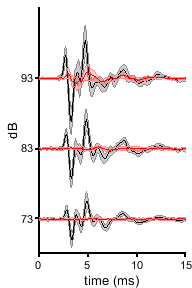


addpath('cjk-2018_10_26-P21_Cx26flfl_tecta8');
cko1 ={EPavg_p012,EPavg_p014,EPavg_p015,EPavg_p016};
rmpath('cjk-2018_10_26-P21_Cx26flfl_tecta8');
addpath('cjk-2018_10_26-P21_cx26flfl_tecta_7');
cko2 ={EPavg_p011,EPavg_p012,EPavg_p013,EPavg_p014};
rmpath('cjk-2018_10_26-P21_cx26flfl_tecta_7');
addpath('cjk-2018_11_12-P21_cx26tectacre_3');
cko3 ={EPavg_p007,EPavg_p008,EPavg_p009,EPavg_p010};
rmpath('cjk-2018_11_12-P21_cx26tectacre_3');
addpath('cjk-2019_01_05-P21_tectacx26flfl_2');
cko4 ={EPavg_p008,EPavg_p009,EPavg_p010,EPavg_p011};
rmpath('cjk-2019_01_05-P21_tectacx26flfl_2');
addpath('cjk-2019_10_07-P21_abr_tectacx26flfl_3');
cko5 ={EPavg_p018,EPavg_p019,EPavg_p020};
rmpath('cjk-2019_10_07-P21_abr_tectacx26flfl_3');
addpath('cjk-2019_10_07-P21_abr_tectacx26flfl_6');
cko6 ={EPavg_p020,EPavg_p021,EPavg_p022,EPavg_p023};
rmpath('cjk-2019_10_07-P21_abr_tectacx26flfl_6');
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_4');
cko7 ={EPavg_p020,EPavg_p021,EPavg_p022};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_4');
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_1');
cko8 = {EPavg_p016,EPavg_p017,EPavg_p018};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_1')
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_3');
cko9 = {EPavg_p015,EPavg_p016,EPavg_p019};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_3');
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_5');
cko10 = {EPavg_p011,EPavg_p012,EPavg_p015};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_5');
addpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_6');
cko11 = {EPavg_p016,EPavg_p017};
rmpath('cjk-2019_10_31-P21_abr_tectacx26flfl_gcamp6_6');


%meancko0 = mean([(-cko1{1,1}.AverageData(:,4))';(-cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))';(cko5{1,1}.AverageData(:,4))';(cko6{1,1}.AverageData(:,4))';(cko7{1,1}.AverageData(:,4))'],1);
meancko10 = mean([(-cko1{1,2}.AverageData(:,4))';(-cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))';(cko5{1,2}.AverageData(:,4))';(cko6{1,2}.AverageData(:,4))';(cko7{1,2}.AverageData(:,4))';(cko8{1,1}.AverageData(:,4))';(cko9{1,1}.AverageData(:,4))';(cko10{1,1}.AverageData(:,4))';(cko11{1,1}.AverageData(:,4))'],1);
meancko20 = mean([(-cko1{1,3}.AverageData(:,4))';(-cko2{1,3}.AverageData(:,4))';(cko3{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))';(cko5{1,3}.AverageData(:,4))';(cko6{1,3}.AverageData(:,4))';(cko7{1,3}.AverageData(:,4))';(cko8{1,2}.AverageData(:,4))';(cko9{1,2}.AverageData(:,4))';(cko10{1,2}.AverageData(:,4))';(cko11{1,2}.AverageData(:,4))'],1);
meancko30 = mean([(-cko1{1,4}.AverageData(:,4))';(-cko2{1,4}.AverageData(:,4))';(cko3{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))';(cko6{1,4}.AverageData(:,4))';(cko8{1,3}.AverageData(:,4))';(cko9{1,3}.AverageData(:,4))';(cko10{1,3}.AverageData(:,4))'],1);

ckomean = {meancko10,meancko20,meancko30};

%stdcko0 = std([(-cko1{1,1}.AverageData(:,4))';(-cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))';(cko5{1,1}.AverageData(:,4))';(cko6{1,1}.AverageData(:,4))';(cko7{1,1}.AverageData(:,4))'],1);
stdcko10 = std([(-cko1{1,2}.AverageData(:,4))';(-cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))';(cko5{1,2}.AverageData(:,4))';(cko6{1,2}.AverageData(:,4))';(cko7{1,2}.AverageData(:,4))';(cko8{1,1}.AverageData(:,4))';(cko9{1,1}.AverageData(:,4))';(cko10{1,1}.AverageData(:,4))';(cko11{1,1}.AverageData(:,4))'],1);
stdcko20 = std([(-cko1{1,3}.AverageData(:,4))';(-cko2{1,3}.AverageData(:,4))';(cko3{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))';(cko5{1,3}.AverageData(:,4))';(cko6{1,3}.AverageData(:,4))';(cko7{1,3}.AverageData(:,4))';(cko8{1,2}.AverageData(:,4))';(cko9{1,2}.AverageData(:,4))';(cko10{1,2}.AverageData(:,4))';(cko11{1,2}.AverageData(:,4))'],1);
stdcko30 = std([(-cko1{1,4}.AverageData(:,4))';(-cko2{1,4}.AverageData(:,4))';(cko3{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))';(cko6{1,4}.AverageData(:,4))';(cko8{1,3}.AverageData(:,4))';(cko9{1,3}.AverageData(:,4))';(cko10{1,3}.AverageData(:,4))'],1);

stdcko = {stdcko10,stdcko20,stdcko30};

figure
hold on
for x = 1:3
shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),flflstd{1,x})
end
for x = 1:3
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(cko1{1,1}.AverageData(:,1),ckomean{1,x}-10*(x-1),stdcko{1,x},'lineprops','r')
    
end
dim =[2,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([ -20 -10 0]);
yticklabels([73 83 93])
ylim([-25 10])
hold off

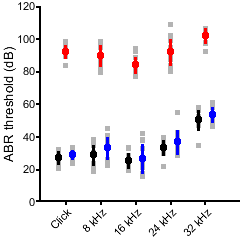


% thresholds with gcamp+ animals too

tectaflclickp21G = [91.0,98,93.1,98];
tectafl8p21G = [95.7,98,84.9,94.5];
tectafl16p21G = [84.0,93.9,83.7,92.0];
tectafl24p21G = [91.3,108.9,87.1,94.3];
tectafl32p21G = [97.8,97.9,106,106];

tectaclickp21G = [24.7,28.6,28.2,27.8,33.4,33.3];
tecta8p21G = [25.9,36.7,34.0,33.1,45.3,40.6];
tecta16p21G = [16.5,24.6,32.8,21.4,41.9,38.0];
tecta24p21G = [35.9,32.7,39.9,30.1,42.6,54.9];
tecta32p21G = [46.2,59.4,52.3,52.6,60.9,60.9];

flflclickp21G = [30.3,23.7,32.4];
flfl8p21G = [35.1,29.3,38.1];
flfl16p21G = [32.8,22.3,27.2];
flfl24p21G = [37.9,29.8,39.2];
flfl32p21G = [55.9,48.2,56.1];

tectaflclickp21 = [tectaflclickp21G,90.1,89.7,89.1,83.7,96.1,89.6,93.9];
tectafl8p21 = [tectafl8p21G,85.2,87.4,83.1,79.1,95.8,82.0,98.1];
tectafl16p21 = [tectafl16p21G,82.6,78.3,79.5,77.0,83.8,82.0,88.2];
tectafl24p21 = [tectafl24p21G,82.4,79.9,83.4,90.5,98.9,91.7,101.9];
tectafl32p21 = [tectafl32p21G,97.8,92.1,97.2,106,106,105.9,106];

tectaclickp21 = [tectaclickp21G,23.8,28.1,28.9,31.8,32.8];
tecta8p21 = [tecta8p21G,26.3,23.7,22.6,38.1,38.1];
tecta16p21 = [tecta16p21G,17.7,15.6,21.9,37.8,25.3];
tecta24p21 = [tecta24p21G,29.9,28.3,39.9,40.0,30.8];
tecta32p21 = [tecta32p21G,51.7,52.0,57.7,50.1,47.4];

flflclickp21 = [flflclickp21G,27.1,22.8,20.3,31.8,31.1,26.2];
flfl8p21 = [flfl8p21G,18.7,23.7,20.9,30.2,34.7,28.4];
flfl16p21 = [flfl16p21G,21.6,23.6,21.6,33.4,28.6,19.1];
flfl24p21 = [flfl24p21G,21.8,29.9,36.1,34.9,37.1,33.0];
flfl32p21 = [flfl32p21G,34.5,50.9,57.8,49.5,52.6,46.7];

% plot all on one graph
figure
hold on
conditions = {'Click','8 kHz','16 kHz','24 kHz','32 kHz'};
ylbl = 'ABR threshold (dB)';
dim = [2.5 2.5];
markSz = [20 20];
color1 = 'k';
color2 = 'r';
color3 = 'b';
compare5offsetM(flflclickp21,flfl8p21,flfl16p21,flfl24p21,flfl32p21,conditions,ylbl,dim,markSz,color1,color2)
compare5(tectaflclickp21,tectafl8p21,tectafl16p21,tectafl24p21,tectafl32p21,conditions,ylbl,dim,markSz,color2,color1)
compare5offsetP(tectaclickp21,tecta8p21,tecta16p21,tecta24p21,tecta32p21,conditions,ylbl,dim,markSz,color3,color1)
ylim([0 120])